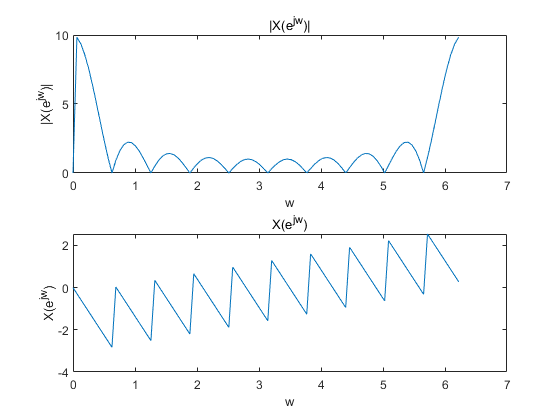

clc;clear all
%5.1(a)代码：
n = 0: 99;
x = (n >= 0 & n <= 9);   % 建立x

%5.1(b)代码：
N=100;
k=0:N-1;
w=2*pi*k/N; %创建100个频率点的向量
M=10;
X=dtftsinc(M,w).*exp(-i*4.5*w); %解析法得到的傅里叶变换
Xfudu=abs(X);
subplot(2,1,1)
plot(w,Xfudu); %幅度谱
xlabel('w');
ylabel('|X(e^{jw})|');
title('|X(e^{jw})|');
subplot(2,1,2)
plot(w,angle(X)); %相位谱
xlabel('w');
ylabel('X(e^{jw})');
title('X(e^{jw})');

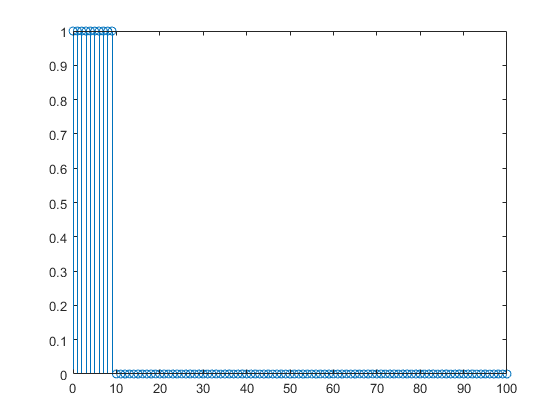


%5.1(c)代码：
figure
k=0:1:100;
w=2*pi*k/100-pi;
a=1*(k>=0);%u[n]
b=1*(k>=10);%u[n-10]
x=a-b;
stem(k,x);

X=fftshift(fft(x))

X =    0.0216 + 0.1534i   0.1836 + 0.4112i   0.4533 + 0.5383i   0.7401 + 0.4966i   0.9474 + 0.3046i   1.0044 + 0.0313i   0.8904 - 0.2263i   0.6420 - 0.3751i   0.3415 - 0.3578i   0.0899 - 0.1718i  -0.0263 + 0.1284i   0.0350 + 0.4490i   0.2569 + 0.6874i   0.5680 + 0.7666i   0.8644 + 0.6615i   1.0447 + 0.4091i   1.0436 + 0.0977i   0.8552 - 0.1615i   0.5371 - 0.2705i   0.1930 - 0.1785i  -0.0601 + 0.0992i  -0.1310 + 0.4840i   0.0133 + 0.8574i   0.3346 + 1.0992i   0.7319 + 1.1283i   1.0726 + 0.9321i   1.2355 + 0.5748i   1.1521 + 0.1806i   0.8337 - 0.1043i   0.3726 - 0.1594i  -0.0827 + 0.0674i  -0.3731 + 0.5377i  -0.3819 + 1.1273i  -0.0776 + 1.6612i   0.4674 + 1.9672i   1.0903 + 1.9345i   1.5823 + 1.5579i   1.7523 + 0.9520i   1.4919 + 0.3301i   0.8219 - 0.0512i  -0.0957 + 0.0341i  -0.9868 + 0.7076i  -1.5300 + 1.9361i  -1.4419 + 3.5196i  -0.5602 + 5.1253i   1.0989 + 6.3608i   3.3267 + 6.8689i   5.7567 + 6.4202i   7.9422 + 4.9781i   9.4580 + 2.7191i


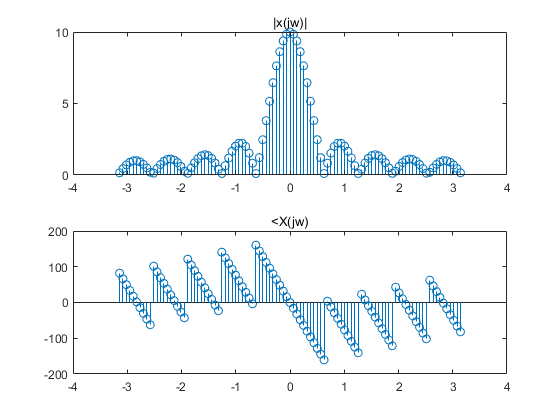

for i=1:101
    X1(i)=abs(X(i));
    X2(i)=angle(X(i))*180/pi;
end
figure
subplot(2,1,1);stem(w,X1);title('|x(jw)|');
subplot(2,1,2);stem(w,X2);title('<X(jw)');